warning off
init_deconvolution


Adding toolboxes and subfolders to path...

projectFolder = /net/store/nbp/users/behinger/projects/deconvolution/git

# Introduction

Subjects are reading sentences on a screen. Using an eyetracker and the EEG-Eye toolbox we add markers of fixation onset into our EEG-Data. We experimentally manipulate sentences that a target word at the end of the sentence is either highly predictable or non-predictable. We expect an N400 between these two predictors.

The data were cleaned for eye-movement related artefacts.

% projectFolder is defined in init_deconvolution
EEG = pop_loadset(fullfile(projectFolder,'..','raw','eeg_synched_msec_0.2hz_lowpass','2_reading_testdata_deconv.set'));

pop_loadset(): loading file /net/store/nbp/users/behinger/projects/deconvolution/git/../raw/eeg_synched_msec_0.2hz_lowpass/2_reading_testdata_deconv.set ...


%EEG.data = EEG.msecdata;
EEG = eeg_checkset(EEG)

EEG =              setname: ''
            filename: '2_reading_testdata_deconv.set'
            filepath: '/net/store/nbp/users/behinger/projects/deconvolution/git/../raw/eeg_synched_msec_0.2hz_lowpass'
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: 'Original file: 02_0.2Hz_IIR_48db.txt'
              nbchan: 69
              trials: 1
                pnts: 1061470
               srate: 500
                xmin: 0
                xmax: 2122.9
               times: [1×1061470 double]
                data: [69×1061470 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×69 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'common'
               event: [1×2031 struct]
             urevent: [1×2031 struct]
    eventdescription: {''  ''  ''  ''  ''  ''  ''  ''  ''  ''  '' 

# Defining the 2x2 factorial design

A 2x2 anova can be reduced to a linear model with two categorical predictors and the interaction. We adopt the widely popular 'formula'-style of model definition. In this case 'y ~ A + B + A:B' (equivalent: 'y ~ A*B') represents the whole model. A and B are our main effects, A:B the interaction. We should specify that we have two categorical factors and we have to specify on which event(s) we want to epoch our data and evaluate the model.

cfgDesign = [];
cfgDesign.eventtype = {'fixation'};

cfgDesign.formula = 'y ~ 1+ cat(level_predictability)*cat(target_fixation)'

cfgDesign =     eventtype: {'fixation'}
      formula: 'y ~ 1+ cat(level_predictability)*cat(target_fixation)'


EEG = dc_designmat(EEG,cfgDesign);

Modeling event(s) [fixation] using formula: y ~ 1+ cat(level_predictability)*cat(target_fixation) 


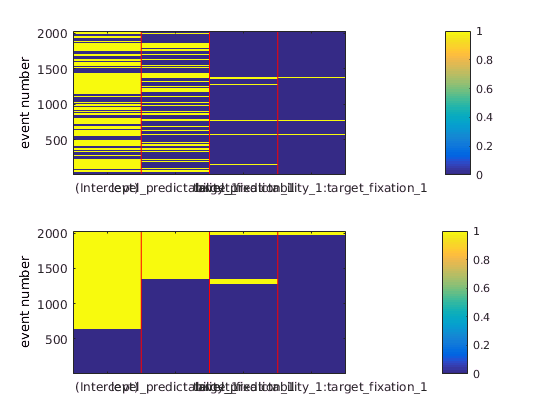

subplot(2,1,1),dc_plotDesignmat(EEG,'sort',0,'figure',0)
subplot(2,1,2),dc_plotDesignmat(EEG,'sort',1,'figure',0)

The two plots show the designmatrix. On the top we have it unsorted, where the y-axis depicts the event in order of appearance. The bottom one is a sorted version. We will discuss the bottom plot. The lower part (all columns are 0) depicts events that are not modeled. These are in our example stimulus onsets. We can ignore those, as a zero in all columns means it will be ignored in the later fit. The first column has only ones. It is called the reference, the constant or the intercept.Each column represents a single predictor or effect. We are using treatment/reference coding (instead of effect-coding) and this assigns a special meaning to the first column: It represents the value of the ERP that is assigned, if all other predictors are zero. So with the second column indicating "predictability=1", the third "target=1" and the fourth the interaction, this means that the first column represents what a trial looks like when predictability is zero and it is not a target. The other predictors depict the respective difference-effect to this reference.

# Timeshift

In order to compensate for the inevitable linear overlap between ERPs, we want to use timeshifting / prepare the designmatrix for the deconvolution step. In this step we generate for each column of the designmatrix timeshifted (by t = 1, t=2, t=3 ...) and append them to the designmatrix.

cfgTimeshift = [];
cfgTimeshift.timelimits = [-1.5,0.8];
cfgTimeshift.method='splines';
cfgTimeshift.timeshiftparam = 40;
EEG = dc_timeshiftDesignmat(EEG,cfgTimeshift);


dc_deconvolveDesignmat(): Timeshifting the designmatrix...
Convolving and adding row 1 from 4 to designmatrix 
Convolving and adding row 2 from 4 to designmatrix 
Convolving and adding row 3 from 4 to designmatrix 
Convolving and adding row 4 from 4 to designmatrix 
...done


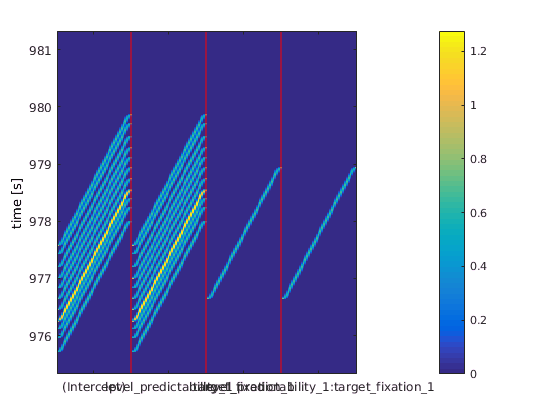

dc_plotDesignmat(EEG,'timeshift',1)

This plot shows how the designmatrix works that achieves linear deconvolution. Each parameter in the designmatrix X spans now over the whole contious timeseries (n samples) instead of a single value per trial. This is done by an expansion of each column into a time-resolved set of columns. The new columns represent the predictor at a given time-point. If graphically we imagine that we predict some EEG-signal along the y/time-axis, then basically we try to predict one sample based on a horizontal slice through the matrix, weighted by to-be-estimated beta-parameters. In the above plot, the horizontal lines represent the actual event onset, see how shortly before (-.3s) and a bit longer afterwards (0.8s) the "staircase" evolves. TODO: Write this one better

# Fit the model

We solve the linear equation: $y=\beta X$ (y=data, X= Designmatrix) for $\beta$ at each point in time. These betas reflect our parameter estimates.

% We have to clean for obvious artefacts, the estimation is very sensitive to big outliers (which are present in this dataset)
winrej = dc_continuousArtifactDetect(EEG);


	So, basicrap.m will be applied over the full range of data.

Please wait. This might take several seconds...

 12 segments were marked.



EEG = dc_continuousArtifactExclude(EEG,'winrej',winrej);


removing 2.7% from design matrix (fill it with zeros) 


EEG= dc_glmfit(EEG,'method','matlab'); % this method is fast but needs lots of ram


dc_glmfit(): Fitting deconvolution model...solving the equation system

 LMfit finished 


# Plot the results

We choose a single electrode and plot all effects.

plotting all parameters


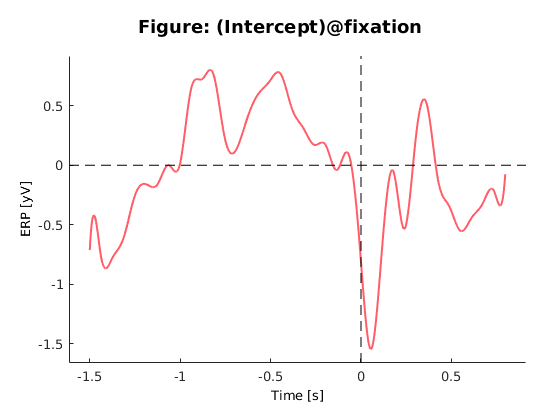

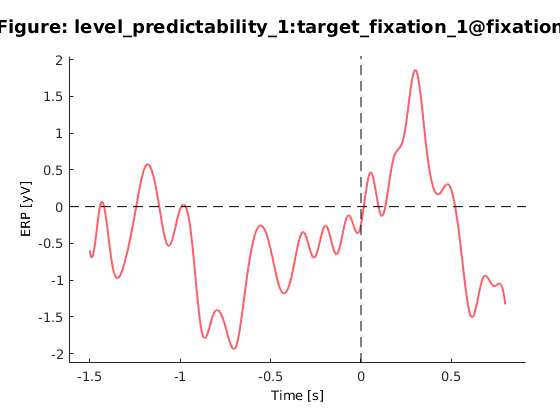

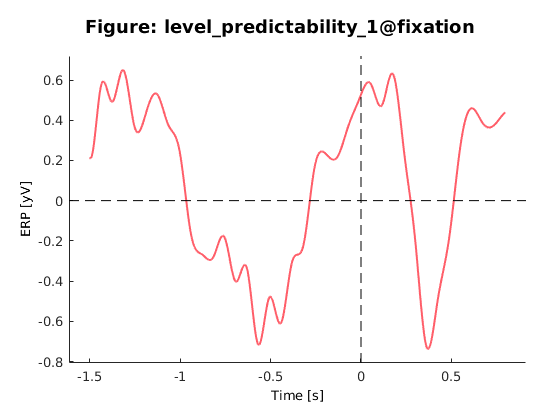

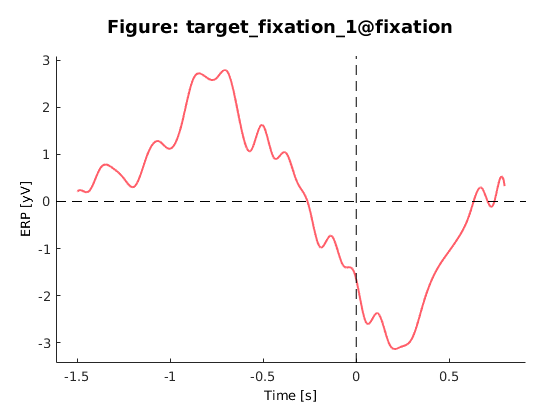

unfold = dc_beta2unfold(EEG);

cfg = [];
cfg.chan = 40;
cfg.add_intercept = 0;
cfg.include_intercept = 0;
cfg.sameyaxis = 'all';
cfg.plotSeparate = 'all';
ax = dc_plotParam(unfold,cfg);

And the same in 2D:

Plotting Topoplots ... Warning: When plotting pvalues in totoplot, use option 'conv' to minimize extrapolation effects


7.26s for row 1/4


Plotting Topoplots ... Warning: When plotting pvalues in totoplot, use option 'conv' to minimize extrapolation effects


11.55s for row 2/4
Plotting Topoplots ... Warning: When plotting pvalues in totoplot, use option 'conv' to minimize extrapolation effects


16.05s for row 3/4
Plotting Topoplots ... Warning: When plotting pvalues in totoplot, use option 'conv' to minimize extrapolation effects


20.97s for row 4/4


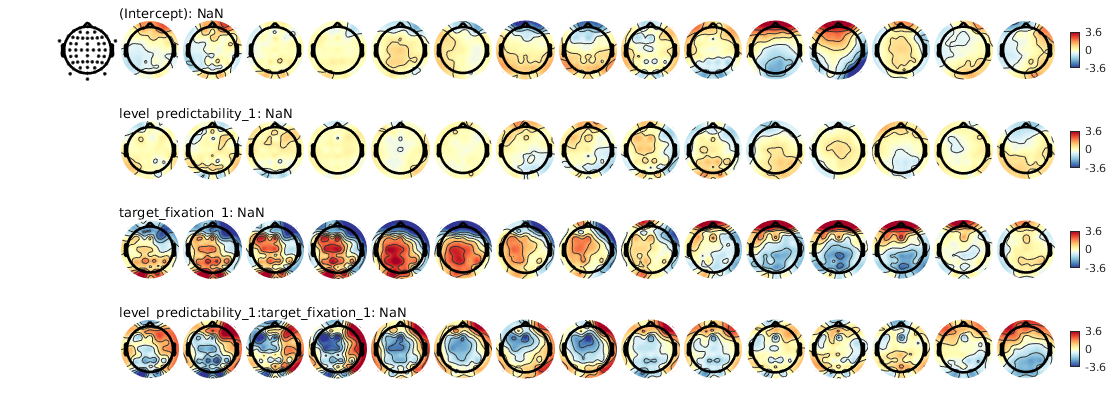

warning off;
cfg = [];
cfg.chan = 1:64;
dc_plotParamTopo(unfold,cfg)

We can have a look at *unfold*:

unfold

unfold =       deconv: [1×1 struct]
        beta: [69×1150×4 double]
       times: [1×1150 double]
    chanlocs: [1×69 struct]
       epoch: [1×4 struct]


Here the unfold.beta contains the beta for each time-point and the epochs represent different predictors at different evaluated levels (e.g. a continous predictor evaluated at the quartiles). 

Information on which epoch is which predictors can be found in EEG.epoch

warning off; % matlab live-view warnings

unfold.epoch(2)

ans =     value: NaN
     name: 'level_predictability_1'
    event: {'fixation'}
